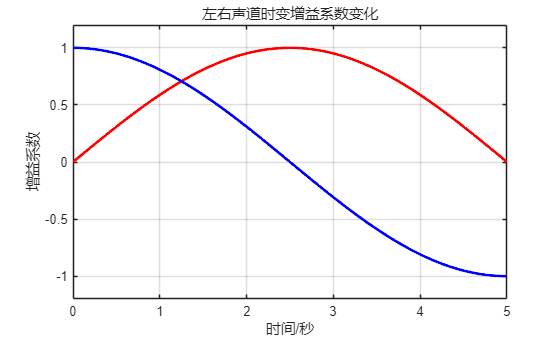

%% 要求：
% 立体声旋转信号
clear; clc;
f = 800;
Fs = 10*f;
T = 5;
A = 1;
t = linspace(0, T, Fs*T);  % 时间向量
x = A*sin(2*pi*f*t);

% 左声道增益系数：正弦变化
G1 = sin(0.1*2*pi*t);
% 右声道增益系数：余弦变化  
G2 = cos(0.1*2*pi* t);
y_left = x .* G1;  % 左声道信号
y_right = x .* G2;  % 右声道信号
figure;

% 增益系数随时间变化
plot(t, G1, 'r-', 'LineWidth', 2);
hold on;
plot(t, G2, 'b-', 'LineWidth', 2);
xlabel('时间/秒');
ylabel('增益系数');
title('左右声道时变增益系数变化');
grid on;
axis([0, T, -1.2, 1.2]);

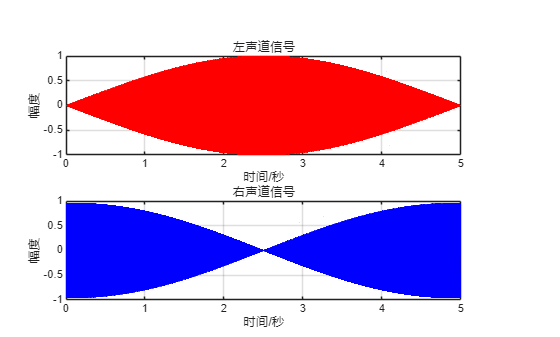

figure;
% 左声道信号
subplot(2,1,1);
plot(t, y_left, 'r', 'LineWidth', 1);
xlabel('时间/秒');
ylabel('幅度');
title('左声道信号');
grid on;
axis([0, T, -1, 1]);

% 右声道信号
subplot(2,1,2);
plot(t, y_right, 'b', 'LineWidth', 1);
xlabel('时间/秒');
ylabel('幅度');
title('右声道信号');
grid on;
axis([0, T, -1, 1]);

% 生成立体声信号矩阵
stereo_signal = [y_left', y_right'];
% sound(stereo_signal, Fs);